# **Visión Artificial. GIEC-GITT.**

# **Sistemas de Visión Artificial. GII-GIC-GISI.**

** Sira Palazuelos, Miguel Angel Garcia, Juan Manuel Miguel**

** Departamento de Electrónica. Universidad de Alcalá.**

**Nombre: Alejandro Fernández Ambrós, Cristina Martínez Toledo**

**Fecha:**

# Tema 4. Ejercicio 3. *Local Features*

El objetivo de esta práctica es mostrar el potencial de las denominadas "*Local Features*". Para ello se va a buscar un objeto dentro de una escena utilizando los detectores y descriptores de características locales.

clear all
close all

Step 1) Leer la imagen de referencia que contiene el objeto de interés.

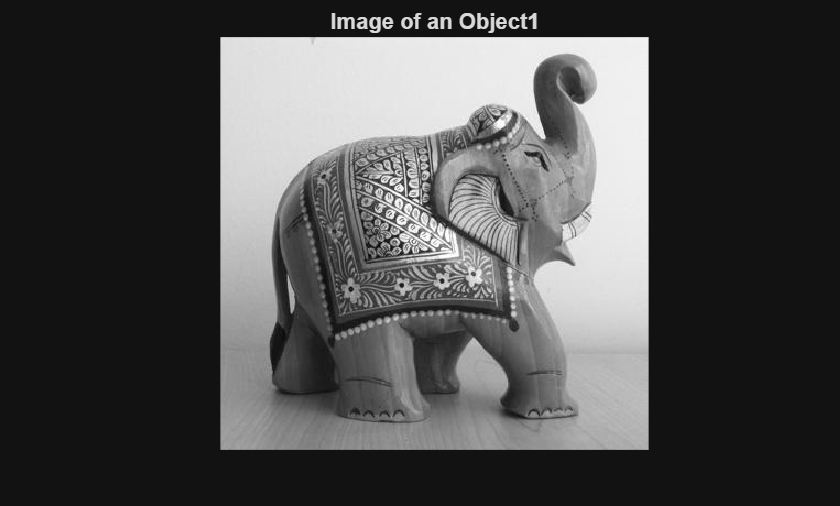

Object1Image = imread('elephant.jpg');
 
figure;
imshow(Object1Image);
title('Image of an Object1');

Se lee la escena que contiene al objeto de interés.

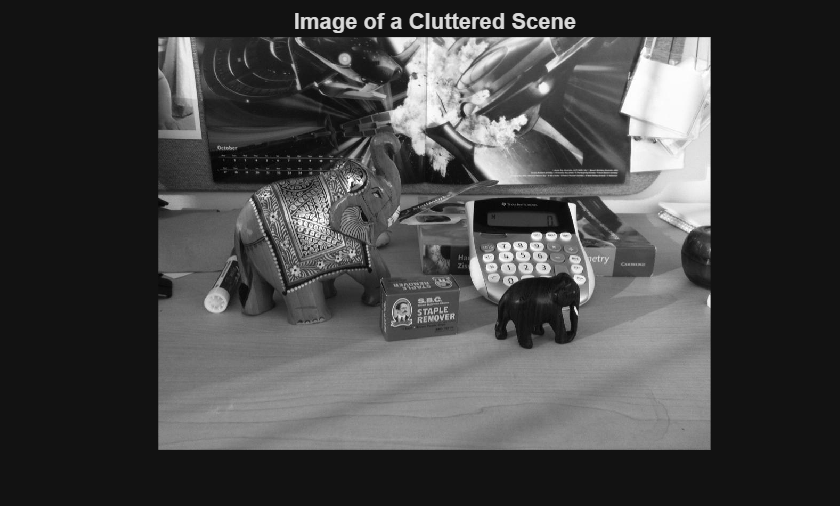

sceneImage = imread('clutteredDesk.jpg');
figure; 
imshow(sceneImage);
title('Image of a Cluttered Scene');

 Step 2) Se detectan las características locales del objeto y de la escena:

% Detect feature points in both images.
Object1Points = detectSURFFeatures(Object1Image);
scenePoints = detectSURFFeatures(sceneImage);

Se visualizan los puntos más fuertes que se encuentran en la imagen del objeto de referencia:

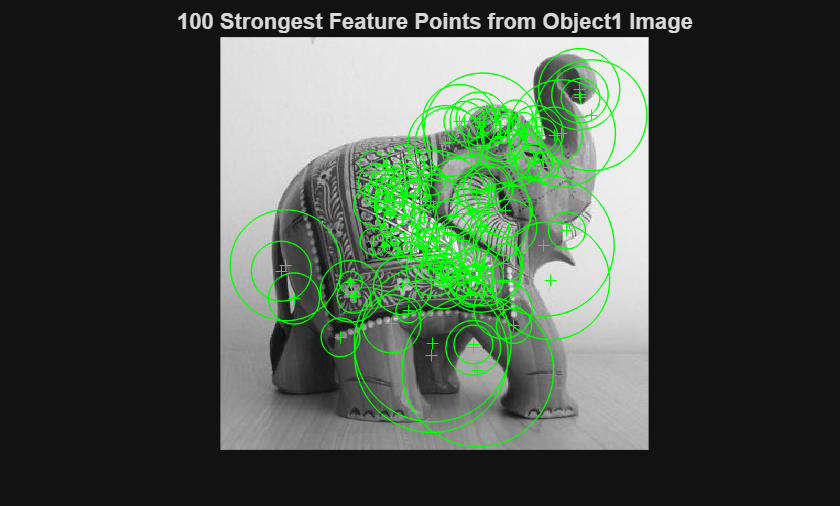

figure; 
imshow(Object1Image);
title('100 Strongest Feature Points from Object1 Image');
hold on;
plot(selectStrongest(Object1Points, 100));

Se visualizan los puntos más fuertes que se encuentran en la imagen de la escena

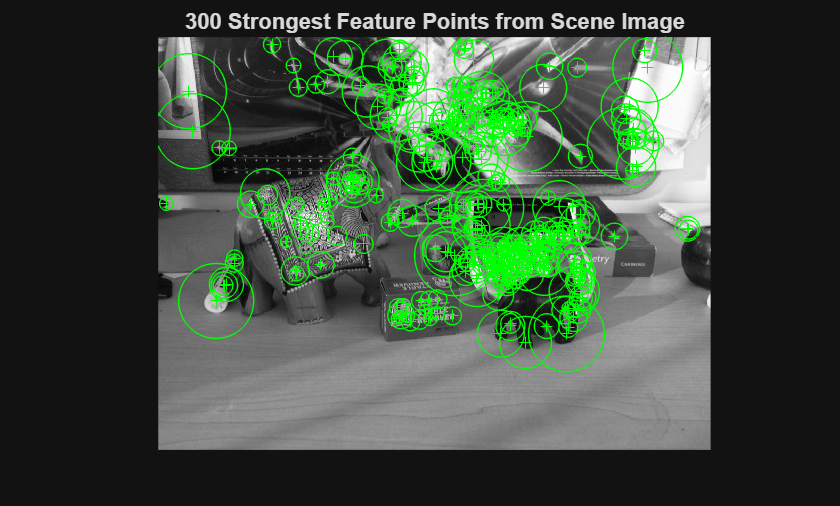

figure; 
imshow(sceneImage);
title('300 Strongest Feature Points from Scene Image');
hold on;
plot(selectStrongest(scenePoints, 300));

Step 3) Se extraen los descriptores de caracterísitcas de ambas imágenes.

[Object1Features, Object1Points] = extractFeatures(Object1Image, Object1Points);
[sceneFeatures, scenePoints] = extractFeatures(sceneImage, scenePoints);

Step 4) Se encuentran las coincidencias (*matches*) y se visualizan.

Object1Pairs = matchFeatures(Object1Features, sceneFeatures, 'MaxRatio', 0.9);
numMatches = size(Object1Pairs,1)

numMatches = 12

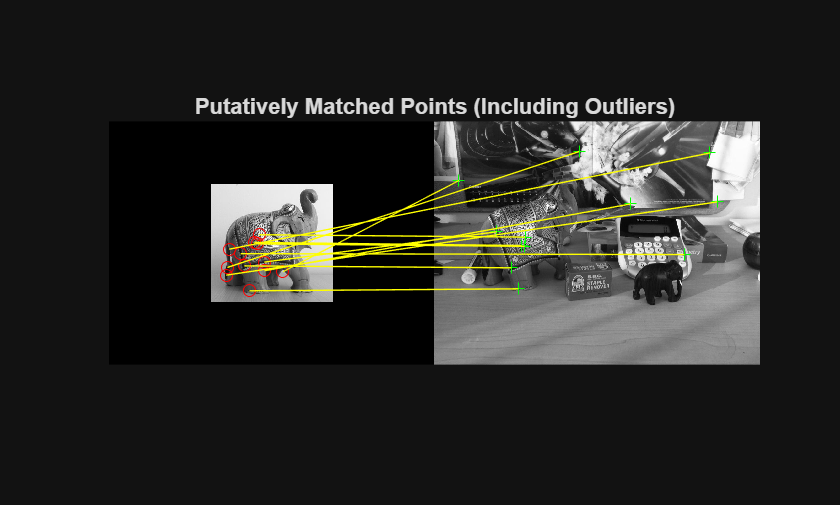

matchedObject1Points = Object1Points(Object1Pairs(:, 1), :);
matchedScenePoints = scenePoints(Object1Pairs(:, 2), :);
figure;
showMatchedFeatures(Object1Image, sceneImage, matchedObject1Points, ...
    matchedScenePoints, 'montage');
title('Putatively Matched Points (Including Outliers)');

Step 5) Se localiza el objeto en la escena usando las coincidencias. 

`estimateGeometricTransform` calcula la transformación relacionando los puntos coincidentes, a la vez que elimina los valores outliers. Esta transformación nos permite localizar el objeto en la escena.

[tform, inlierObject1Points, inlierScenePoints] = estimateGeometricTransform(matchedObject1Points, matchedScenePoints, 'affine');
numInliers = inlierObject1Points.Count

numInliers = 4

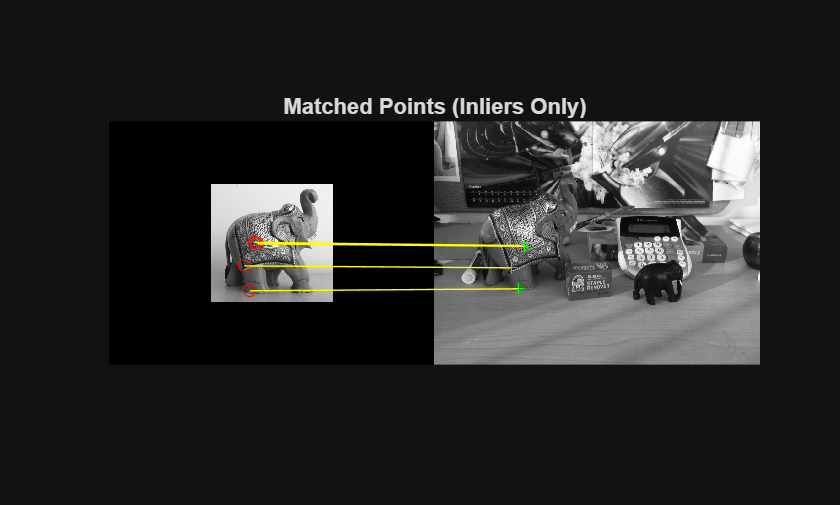

figure;
showMatchedFeatures(Object1Image, sceneImage, inlierObject1Points, inlierScenePoints, 'montage');
title('Matched Points (Inliers Only)');

Se obtiene el polígono delimitador de la imagen de referencia.

Object1Polygon = [1, 1;...                           % top-left
        size(Object1Image, 2), 1;...                 % top-right
        size(Object1Image, 2), size(Object1Image, 1);... % bottom-right
        1, size(Object1Image, 1);...                 % bottom-left
        1, 1];                   % top-left again to close the polygon 

Se transforma el polígono en el sistema de coordenadas de la imagen de destino. El polígono transformado indica la ubicación del objeto1 en la escena.

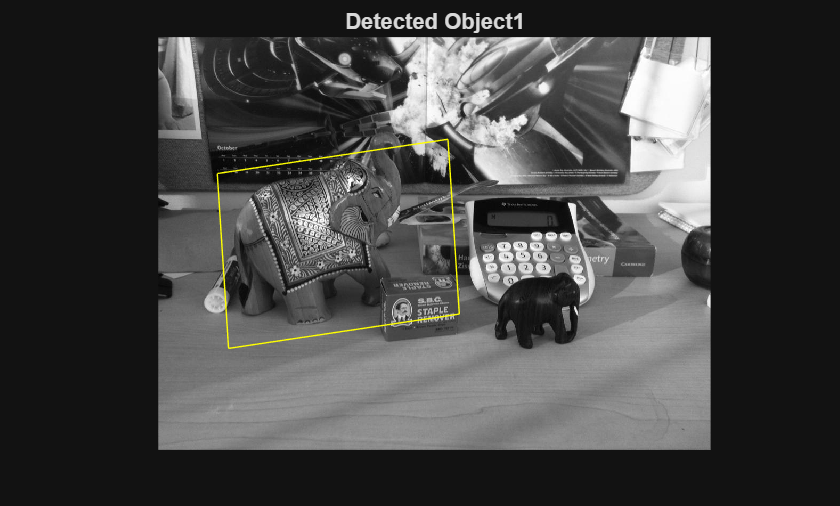

newObject1Polygon = transformPointsForward(tform, Object1Polygon);    

figure;
imshow(sceneImage);
hold on;
line(newObject1Polygon(:, 1), newObject1Polygon(:, 2), 'Color', 'y');
title('Detected Object1');

Se pide:

- Repita el proceso anterior pero buscando otro objeto de la escena, en este caso la caja de la grapadora, cuya imagen es `'stapleRemover.jpg'`. Además utilice el detector y descriptor BRISK ([`detectBRISKFeatures`](https://es.mathworks.com/help/vision/ref/detectbriskfeatures.html)). Compruebe cuántos pares de puntos empareja el algoritmo visualizando la salida de la función **matchFeatures**.

- Añada ruido gaussiano de varianza `0.001` a la imagen `'clutteredDesk.jpg'` y repita el apartado anterior. Compare el número de emparejamientos y de `inliers `con los obtenidos sin ruido. ¿Sigue siendo posible localizar correctamente el objeto?

- Repita el apartado anterior utilizando ruido gaussiano de varianza `0.01`. Compare nuevamente el número de emparejamientos y de `inliers`. ¿Es posible localizar el objeto?

- Aplique a la imagen ruidosa alguna técnica de reducción de ruido estudiada previamente y repita el proceso. ¿Mejora el resultado? Justifique la respuesta a partir del número de correspondencias obtenidas y de la localización final del objeto.

Sin ruido: 11 emparejamientos
    247   1611
    442    947
    513   1148
    587   1074
    590   1075
    598   1092
    618   1125
    656   1159
    708   1541
    719   2050
    722   2050



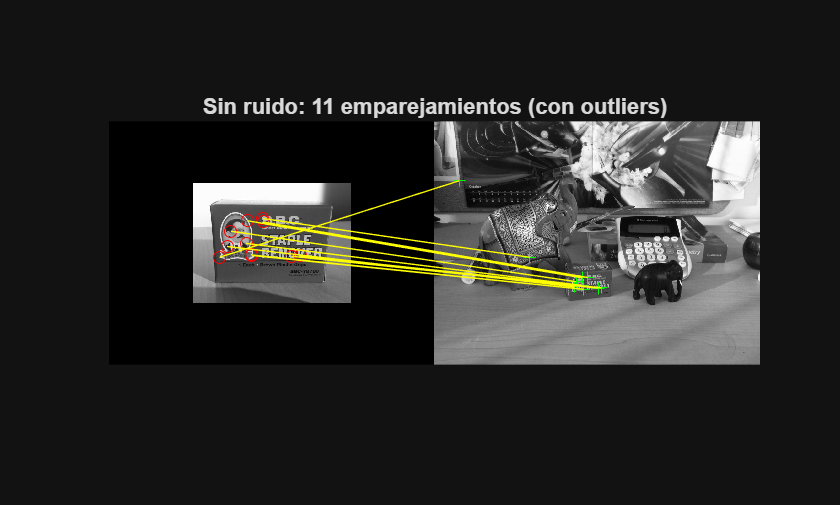

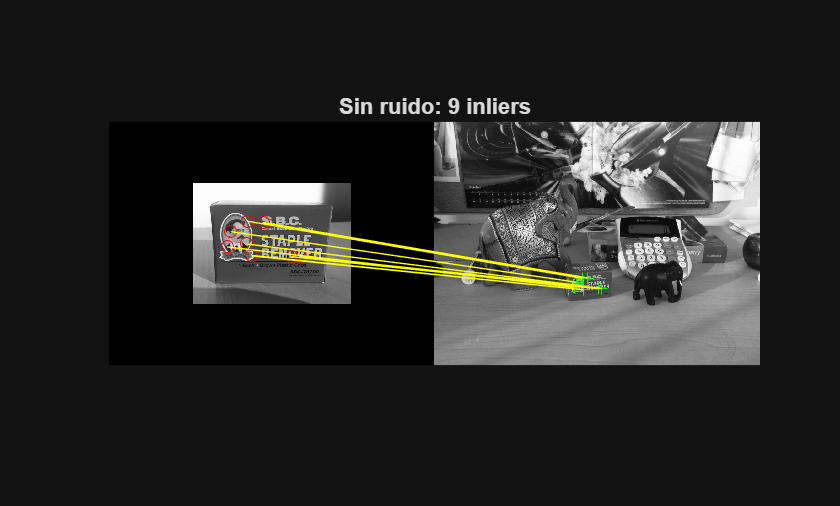

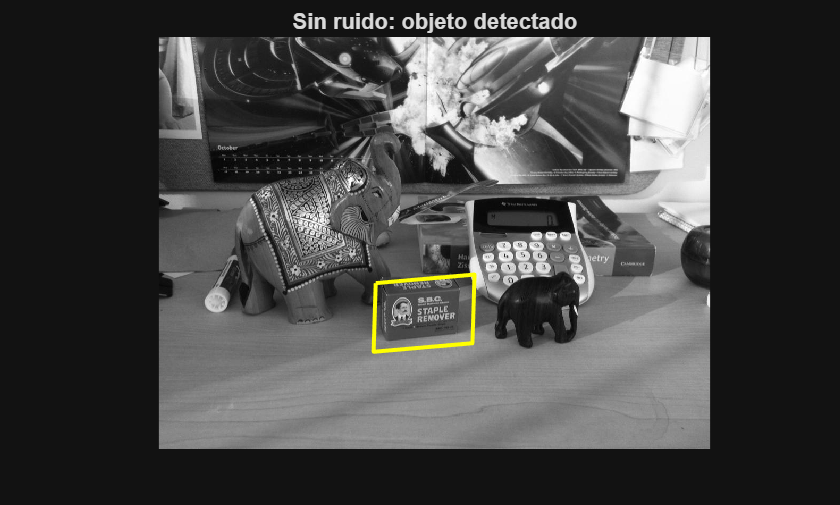

%% Apartado 1: buscar la grapadora con BRISK (sin ruido)
objImg = imread('stapleRemover.jpg');   % objeto a buscar
sceneImage = imread('clutteredDesk.jpg');   % escena

% buscarObjeto (definida al final) hace todo el proceso y devuelve:
% nº de puntos detectados en la escena, nº de emparejamientos y nº de inliers
[p1, m1, i1] = buscarObjeto(objImg, sceneImage, 'Sin ruido');

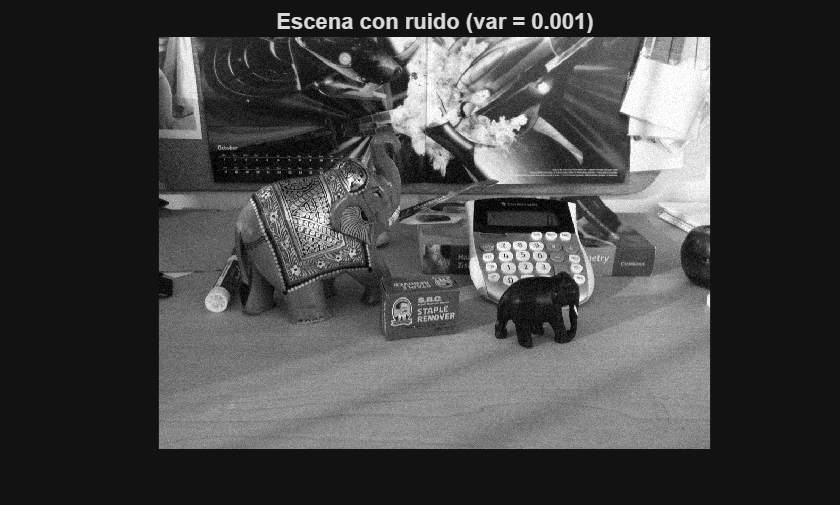


%% Apartado 2: ruido gaussiano de varianza 0.001
% imnoise(imagen, 'gaussian', media, varianza). Trabaja con la imagen
% escalada a [0,1]: varianza 0.001 equivale a una desviación típica de
% ~0.03, unos 8 niveles de gris de 255
escenaRuido1 = imnoise(sceneImage, 'gaussian', 0, 0.001);
figure; imshow(escenaRuido1); title('Escena con ruido (var = 0.001)');

Ruido var 0.001: 6 emparejamientos
    587   1193
    590   1194
    591   1196
    598   1209
    629   1254
    708   1648



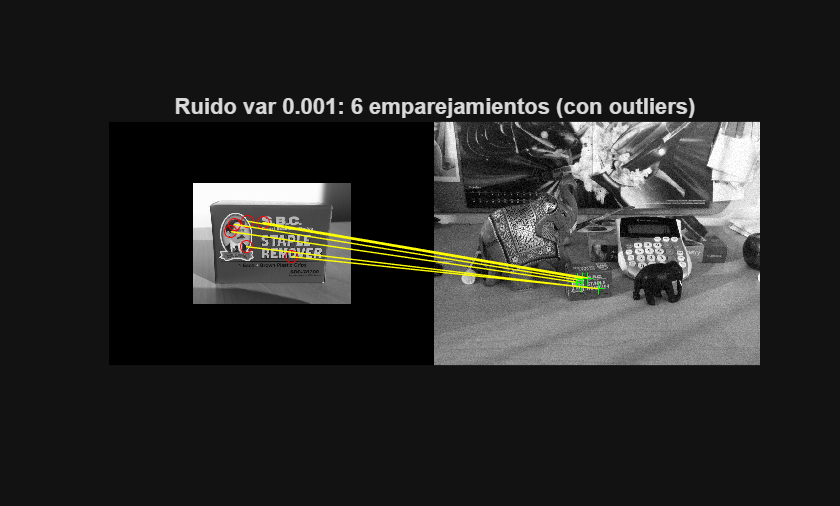

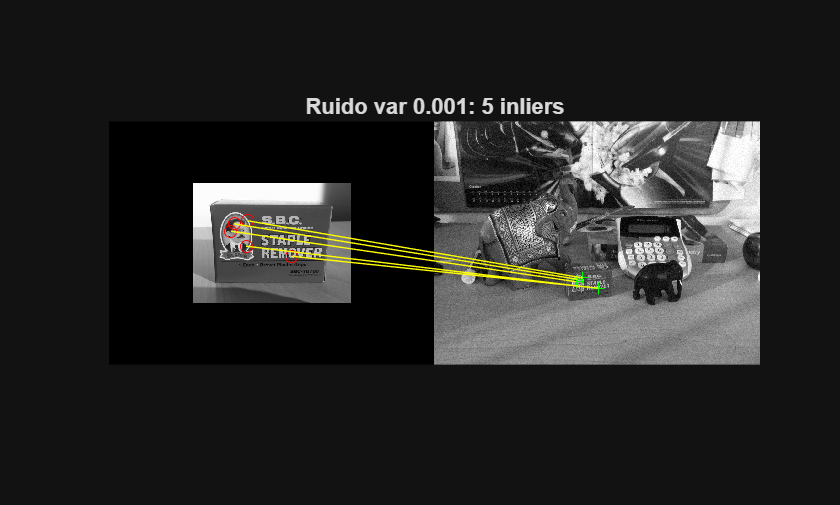

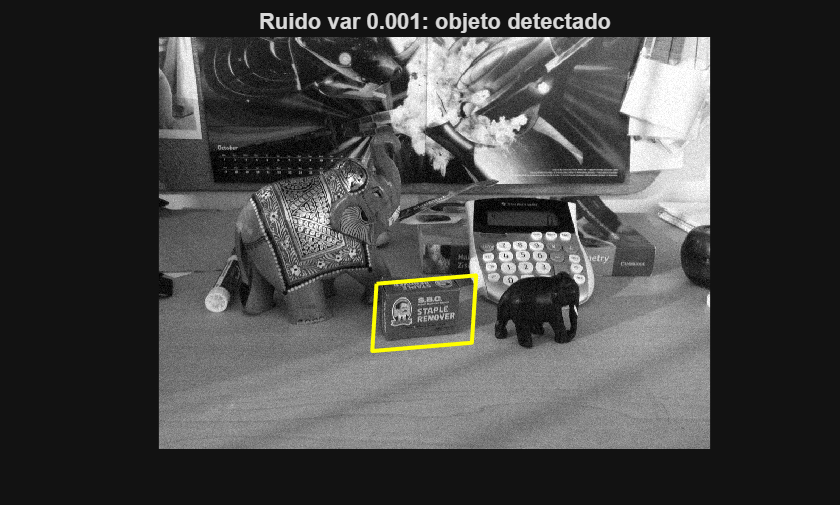


[p2, m2, i2] = buscarObjeto(objImg, escenaRuido1, 'Ruido var 0.001');

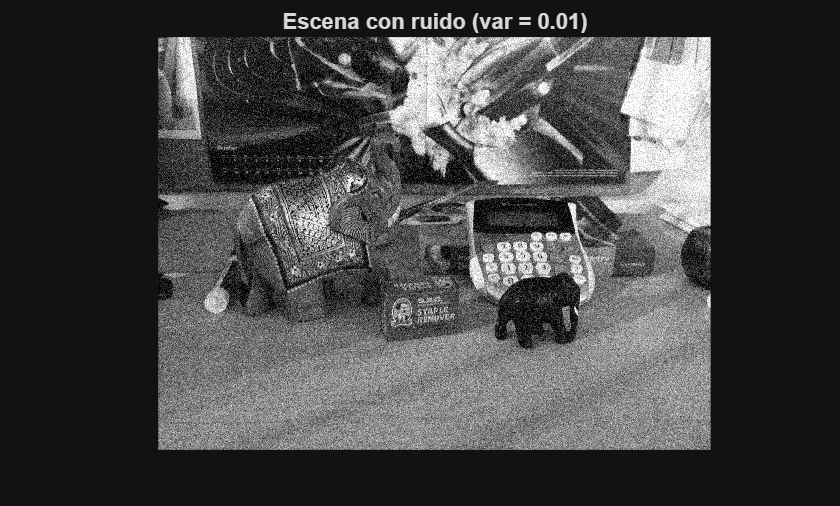


%% Apartado 3: ruido gaussiano de varianza 0.01
% Desviación típica ~0.1, unos 25 niveles de gris: mucho más ruido
escenaRuido2 = imnoise(sceneImage, 'gaussian', 0, 0.01);
figure; imshow(escenaRuido2); title('Escena con ruido (var = 0.01)');

Ruido var 0.01: 4 emparejamientos
     58    314
     62    385
    432    921
    722   9101



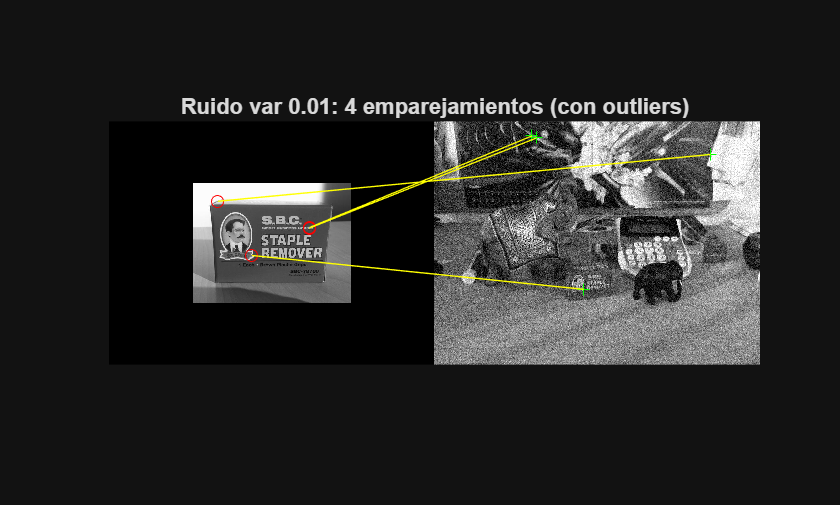

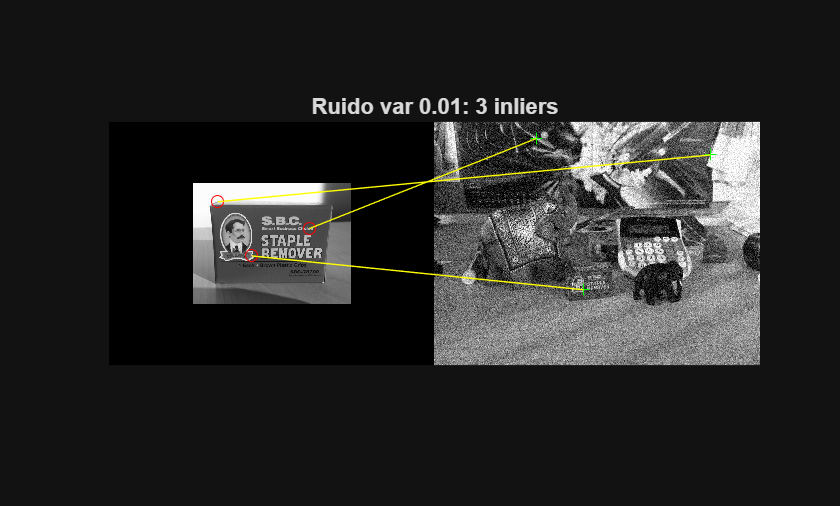

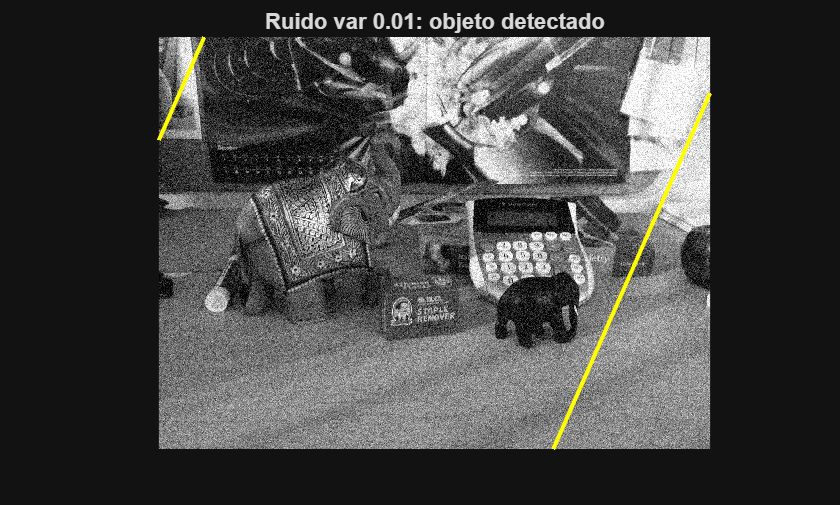


[p3, m3, i3] = buscarObjeto(objImg, escenaRuido2, 'Ruido var 0.01');

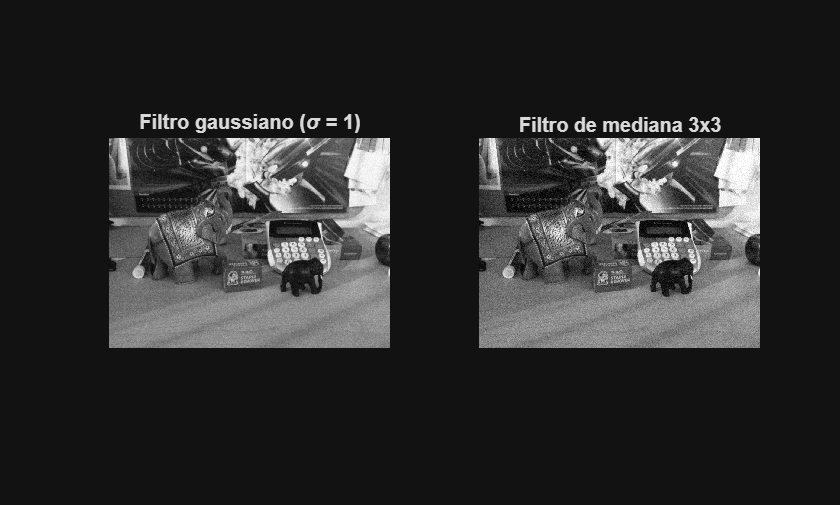


%% Apartado 4: reducir el ruido y repetir
% Filtro gaussiano (suaviza promediando cada píxel con sus vecinos;
% adecuado para ruido gaussiano). El 1 es la sigma: cuánto suaviza
escenaFiltradaG = imgaussfilt(escenaRuido2, 1);

% Filtro de mediana 3x3 (cada píxel se sustituye por la mediana de su
% vecindad 3x3; reduce ruido conservando mejor los bordes)
escenaFiltradaM = medfilt2(escenaRuido2, [3 3]);

figure
subplot(1,2,1); imshow(escenaFiltradaG); title('Filtro gaussiano (\sigma = 1)');
subplot(1,2,2); imshow(escenaFiltradaM); title('Filtro de mediana 3x3');

Ruido 0.01 + gaussiano: 2 emparejamientos
   629   240
   719   662



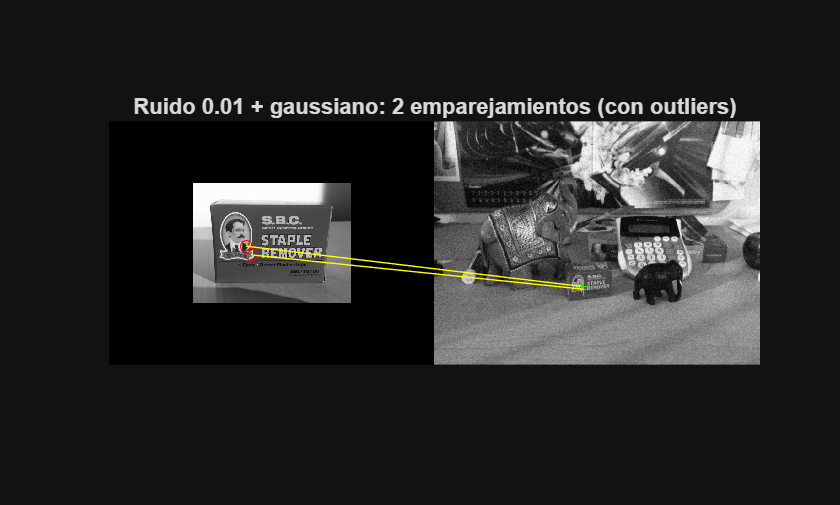

Ruido 0.01 + gaussiano: menos de 3 emparejamientos, no se puede localizar el objeto



[p4, m4, i4] = buscarObjeto(objImg, escenaFiltradaG, 'Ruido 0.01 + gaussiano');

Ruido 0.01 + mediana: 5 emparejamientos
      4    592
    433    705
    442    517
    719   1201
    722   1201



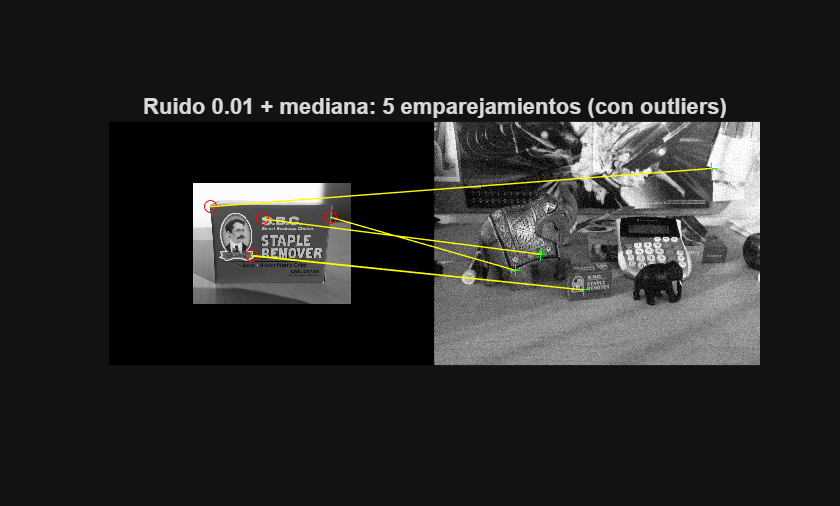

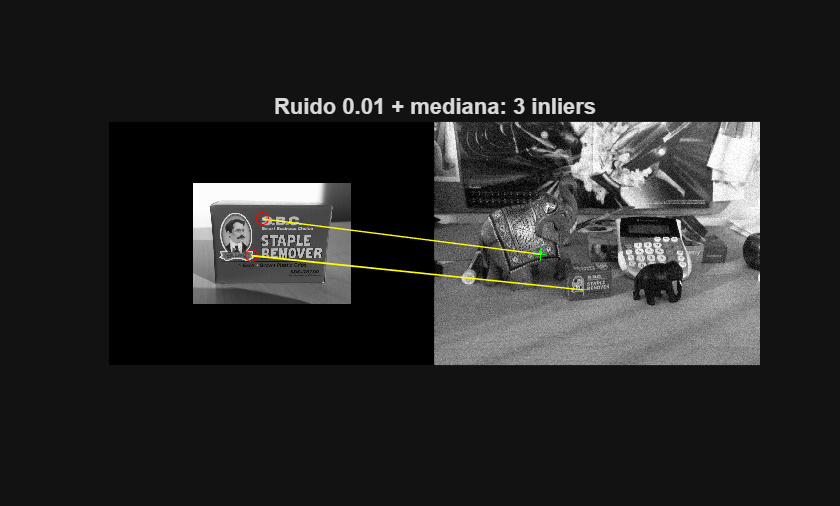

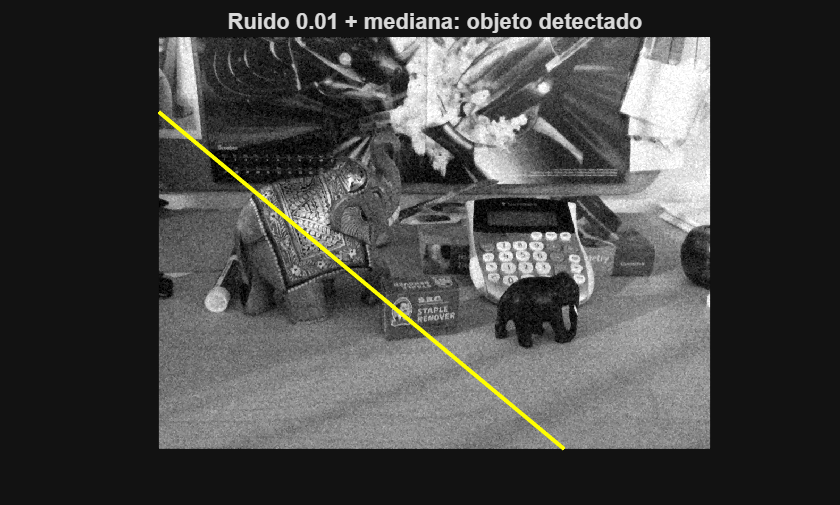

[p5, m5, i5] = buscarObjeto(objImg, escenaFiltradaM, 'Ruido 0.01 + mediana');


%% Tabla resumen para comparar todos los casos
Caso = {'Sin ruido'; 'Ruido 0.001'; 'Ruido 0.01'; ...
    'Ruido 0.01 + gaussiano'; 'Ruido 0.01 + mediana'};
PuntosEscena = [p1; p2; p3; p4; p5];
Emparejamientos = [m1; m2; m3; m4; m5];
Inliers = [i1; i2; i3; i4; i5];
tablaResumen = table(Caso, PuntosEscena, Emparejamientos, Inliers)

tablaResumen = 5×4 table
               Caso               PuntosEscena    Emparejamientos    Inliers
    __________________________    ____________    _______________    _______

    {'Sin ruido'             }        2462              11              9   
    {'Ruido 0.001'           }        2587               6              5   
    {'Ruido 0.01'            }        9888               4              3   
    {'Ruido 0.01 + gaussiano'}        1173               2              0   
    {'Ruido 0.01 + mediana'  }        1774               5              3   

	Get insights using Copilot


Funciones auxiliares:


%% Función que busca un objeto en una escena con BRISK
% Recibe la imagen del objeto, la escena y un nombre para los títulos (indicar de qué caso se trata)
function [numPuntosEscena, numMatches, numInliers] = buscarObjeto(objImg, escena, nombre)

% --- Paso 2: detectar puntos característicos con BRISK ---
objPoints = detectBRISKFeatures(objImg);
scenePoints = detectBRISKFeatures(escena);
numPuntosEscena = scenePoints.Count; % cuántos puntos hay en la escena

% --- Paso 3: calcular el descriptor de cada punto ---
[objFeatures, objPoints] = extractFeatures(objImg, objPoints);
[sceneFeatures, scenePoints] = extractFeatures(escena, scenePoints);

% --- Paso 4: emparejar descriptores ---
% Se compara cada huella del objeto con todas las de la escena y se empareja con la más parecida
% 'MaxRatio', 0.9: Es un filtro de calidad basado en la prueba de relación de Lowe para descartar coincidencias falsas o ambiguas:
% - Para cada punto del objeto, MATLAB busca los dos puntos más parecidos en la escena.
% - Divide la distancia al más cercano entre la distancia al segundo más cercano.
%   - Si ese resultado es menor a 0.9, la coincidencia se acepta. 
%   - Si es mayor o igual a 0.9, significa que ambos candidatos se parecen demasiado entre sí (hay ambigüedad) y se descarta.
% Devuelve una matriz de dos columnas: indice de la caracteristica en el obj y en la escena
pares = matchFeatures(objFeatures, sceneFeatures, 'MaxRatio', 0.9);
numMatches = size(pares, 1); % nº de filas = nº de parejas

% Salida de matchFeatures: cada fila = [nº punto objeto, nº punto escena]
disp([nombre, ': ', num2str(numMatches), ' emparejamientos'])
disp(pares)

% Me quedo solo con los puntos que tienen pareja
matchedObj = objPoints(pares(:, 1), :);
matchedScene = scenePoints(pares(:, 2), :);

figure
showMatchedFeatures(objImg, escena, matchedObj, matchedScene, 'montage');
title([nombre, ': ', num2str(numMatches), ' emparejamientos (con outliers)']);

% --- Paso 5: estimar la transformación y localizar el objeto ---
numInliers = 0;
% Para calcular una transformación afín, se necesita un mínimo de 3 pares de puntos no colineales. 
% Si hay menos de 3 coincidencias, el script detiene la ejecución para evitar errores.
if numMatches < 3
    disp([nombre, ': menos de 3 emparejamientos, no se puede localizar el objeto'])
    return
end

% Siempre se cuelan parejas erróneas, outliers. 
% estimateGeometricTransform busca la transformación (mover, girar, escalar, inclinar) con la que la mayoría de las parejas encajan a la vez. 
% Las parejas que encajan con esa transformación son los inliers (buenas). Las que no encajan se descartan.
% try/catch por si la estimación falla (por ejemplo, porque casi todas las parejas son falsas)
try
    [tform, inlierObj, inlierScene] = estimateGeometricTransform(matchedObj, matchedScene, 'affine');
catch
    disp([nombre, ': no se ha podido estimar la transformación'])
    return
end
numInliers = inlierObj.Count;

figure
showMatchedFeatures(objImg, escena, inlierObj, inlierScene, 'montage');
title([nombre, ': ', num2str(numInliers), ' inliers']);

% Rectángulo que rodea la imagen del objeto (sus 4 esquinas + cierre)
ancho = size(objImg, 2);
alto = size(objImg, 1);
poligono = [1, 1; ancho, 1; ancho, alto; 1, alto; 1, 1];

% Aplicar la transformación a esas 4 esquinas.
% Es decir, calcula dónde caen las esquinas de la foto de la grapadora dentro de la escena.
nuevoPoligono = transformPointsForward(tform, poligono);

figure
imshow(escena)
hold on
line(nuevoPoligono(:, 1), nuevoPoligono(:, 2), 'Color', 'y', 'LineWidth', 2);
hold off
title([nombre, ': objeto detectado']);
end

Se ha repetido el proceso del ejemplo buscando la caja de la grapadora (stapleRemover.jpg) en la escena clutteredDesk.jpg, usando BRISK como detector y descriptor. BRISK detecta esquinas, es invariante a escala y rotación y usa un descriptor binario: cada bit procede de comparar la intensidad de dos píxeles del entorno del punto, y los descriptores se comparan con la distancia de Hamming (número de bits distintos).

En la escena se detectan 2462 puntos. matchFeatures, con el criterio MaxRatio = 0,9, devuelve 11 emparejamientos. Su salida es una matriz de 11 filas y 2 columnas, donde cada fila contiene el índice del punto en la imagen del objeto y el de su pareja en la escena.

A partir de ellos, estimateGeometricTransform estima una transformación afín. Elige repetidamente tríos de parejas al azar, calcula la transformación correspondiente y se queda con la que satisfacen más parejas. Las parejas compatibles con ella son los inliers (9 de 11) y el resto se descartan como outliers.

Para localizar el objeto se toma el rectángulo formado por las cuatro esquinas de la imagen de referencia, que coincide aproximadamente con el contorno de la caja, y se transforma con la transformación estimada a las coordenadas de la escena. El polígono resultante rodea correctamente la caja de la grapadora.

Al añadir ruido gaussiano de varianza 0,001, el número de puntos detectados en la escena aumenta ligeramente (2587), porque el ruido genera algunas esquinas falsas. Los emparejamientos bajan de 11 a 6 y los inliers de 9 a 5: el ruido altera la intensidad de los píxeles y, por tanto, los bits del descriptor, de modo que algunas parejas correctas dejan de reconocerse. Aun así, el objeto sigue localizándose correctamente, ya que 5 parejas compatibles con la misma transformación son suficientes para estimarla de forma fiable.

Con varianza 0,01 el efecto del ruido es mucho mayor. Los puntos detectados en la escena se multiplican por cuatro (9888), ya que el detector encuentra esquinas en el propio ruido, y los emparejamientos bajan a 4, con 3 inliers. El objeto no se localiza: el polígono transformado queda prácticamente fuera de la imagen y solo se ven líneas sueltas sin relación con la caja.

Los 3 inliers no indican una localización correcta. Una transformación afín tiene 6 parámetros y se determina exactamente con 3 parejas de puntos, por lo que con 3 parejas siempre existe una transformación que las cumple todas, sean correctas o no. Solo cuando más de 3 parejas son compatibles con la misma transformación se puede considerar que la localización está verificada. En la figura de inliers se comprueba que las parejas apuntan a zonas de la escena que no corresponden a la caja.

Después, se aplicaron a la imagen con ruido de varianza 0,01 dos técnicas de reducción de ruido: un filtro gaussiano (σ = 1) y un filtro de mediana de 3×3. Ambos filtros reducen mucho el número de puntos detectados (1173 con el gaussiano y 1774 con la mediana, frente a 9888 sin filtrar), porque eliminan la mayoría de las esquinas falsas producidas por el ruido. Sin embargo, el resultado no mejora. Con el filtro gaussiano solo se obtienen 2 emparejamientos, insuficientes para estimar la transformación. Con la mediana se obtienen 5 emparejamientos y 3 inliers, pero por el mismo motivo que en el apartado anterior esos 3 inliers no verifican nada, y el polígono resultante es una línea que cruza la escena, lejos de la caja. 

La explicación es que el filtrado, además de eliminar ruido, suaviza las esquinas y los detalles finos reales del objeto (bordes y letras de la caja), que son precisamente las estructuras en las que se basan el detector y el descriptor. La información que el ruido ha destruido no se recupera filtrando, y la escena filtrada se parece menos a la imagen de referencia, que no está filtrada, por lo que los descriptores coinciden peor. El filtro de mediana obtiene algo más de emparejamientos que el gaussiano porque conserva mejor los bordes, pero no lo suficiente para localizar el objeto.

En conclusión, las características locales permiten localizar un objeto en una escena compleja aunque aparezca con otro tamaño, posición y orientación, y son robustas frente a un nivel de ruido bajo. Con ruido elevado, el detector genera muchas esquinas falsas y los descriptores binarios se alteran, de modo que las correspondencias correctas desaparecen. En este caso, el filtrado previo no permite recuperar la localización.